%clear all
cbf_viz = cbf(); 

eta_test = [0; 0; 0]; 
cbf_viz.f(eta_test(1)) - eta_test(2)

ans = 0

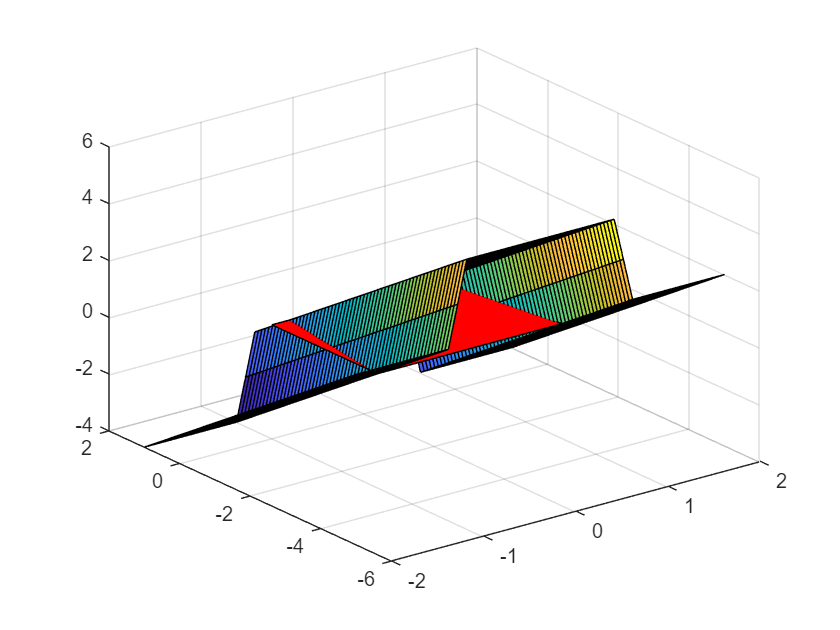


x_test = -2:0.1:2; 
y_test = -5:0.1:1; 

[X, Y] = meshgrid(x_test, y_test); 

DOC = zeros(size(X)); 

for r = 1:size(X, 1)
    for c = 1:size(X,2)
        DOC(r, c) = cbf_viz.f(X(r,c)); 
    end
end

Z = DOC - Y; %this is h

surf(X,Y,Z)

hold on

x_doc = -cbf_viz.k2;
y_doc = -cbf_viz.k1; 
width = cbf_viz.k2; 
hight = cbf_viz.k1;
rect_x = [x_doc, x_doc, x_doc + width*2, x_doc + width*2]; 
rect_y = [y_doc, y_doc + hight, y_doc + hight, y_doc]; 
rect_z = [1, 1, 1, 1]*(0);

patch(rect_x, rect_y, rect_z, 'r')

hold off